% example script that recreates the plots shown in the README document
close all;
clear all;

% Change this data file name below to plot different files
load('data/Matlab/RW1')

## First we show sample plot of the first low current discharging and charging cycles

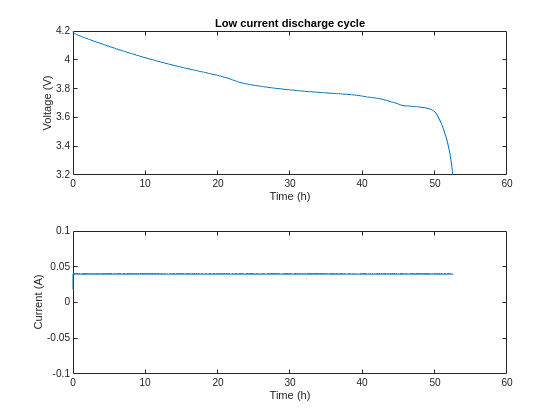

steps = data.step; % save steps array to new variable

% search for instances of low current discharge step
inds = []; % initialize index array
for(i=1:length(steps))
    if(strcmp(data.step(i).comment,'low current discharge at 0.04A'))
        inds = [inds, i];
    end
end

RT = steps(inds(1)).relativeTime/3600; % relative time in hours
V = steps(inds(1)).voltage; % voltage
I = steps(inds(1)).current; % current

figure % plot voltage and current profiles
subplot(2,1,1)
% plot voltage profile
plot(RT,V)
title('Low current discharge cycle')
xlabel('Time (h)');
ylabel('Voltage (V)');

subplot(2,1,2)
% plot current profile
plot(RT,I)
ylim([-.1,.1])
xlabel('Time (h)');
ylabel('Current (A)');

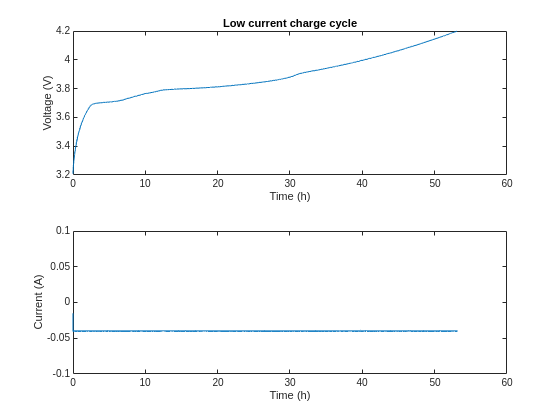


% search for first instance of low current charge step
while( ~strcmp(steps(i).comment,'low current charge'))
    i=1+1;
end

RT = steps(i).relativeTime/3600; % relative time in hours
V = steps(i).voltage; % voltage
I = steps(i).current; % current

figure % plot voltage and current profiles
subplot(2,1,1)
% plot voltage profile
plot(RT,V)
title('Low current charge cycle')
xlabel('Time (h)');
ylabel('Voltage (V)');

subplot(2,1,2)
% plot current profile
plot(RT,I)
ylim([-.1,.1])
xlabel('Time (h)');
ylabel('Current (A)');

## Next, the constant load profiles that are run after every 50 random walk

discharge cycles are plotted using

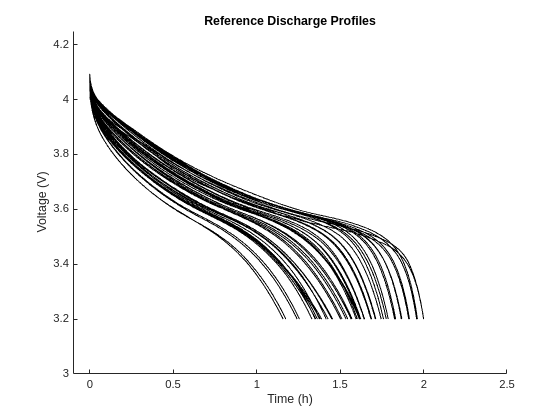

% initialize plot
figure, hold on
xlim([-.1,2.5])
ylim([3,4.25])
xlabel('Time (h)');
ylabel('Voltage (V)');
title('Reference Discharge Profiles')

for i = 1:length(steps) % search through the array of step structures
    if strcmp(steps(i).comment,'reference discharge')
        RT = steps(i).relativeTime/3600; % relative time in hours
        V = steps(i).voltage; % voltage
        plot(RT,V,'k')
    end
end

## We can benchmark the battery?s capacity by integrating current over the

reference cycles. The next plot shows this capacity measurement vs date.

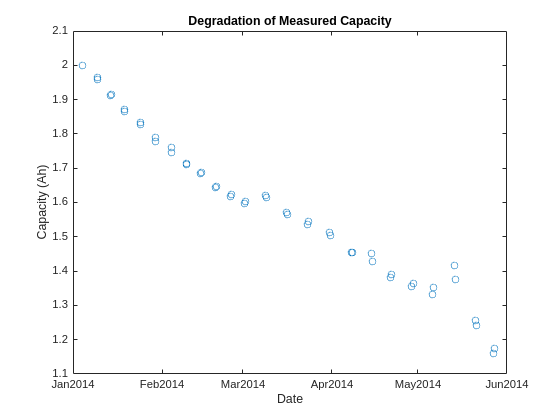

counter = 0; % initialize counters

for i = 1:length(steps) % search through the array of step structures
    if strcmp(steps(i).comment,'reference discharge')
        counter = counter+1;

        % save the date of this reference discharge step
        date(counter) = datenum(steps(i).date);

        % save the battery capacity measured by integrating current
        capacity(counter) = trapz(steps(i).relativeTime/3600,data.step(i).current);
    end
end

% plot the data
figure
plot(date,capacity,'o')
datetick('x','mmmyyyy')
xlabel('Date');
ylabel('Capacity (Ah)');
title('Degradation of Measured Capacity')

## The next code snippet shows how the resting periods after each reference

discharge can be grouped with the corresponding reference discharge cycle and added to the plot above.

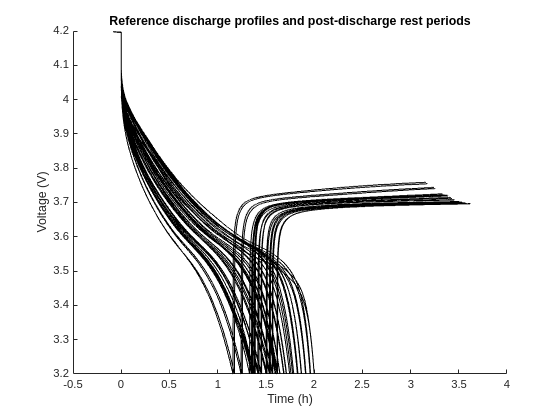

% initialize Reference Discharge Struct that will hold indexes of reference
% discharge steps and the rest steps that come imediately before and after
RefDis.repition{1}.indexes = 0;

% initialize loop parameters
counter = 0;
for i = 1:length(data.step)
    if strcmp(steps(i).comment,'reference discharge')
        counter = counter+1;
        if strcmp(steps(i-1).comment,'rest post reference charge')
            RefDis.repition{counter}.indexes = [i-1, i];
        else
            RefDis.repition{counter}.indexes = i;
        end
    end

    if strcmp(steps(i).comment,'rest post reference discharge')
        RefDis.repition{counter}.indexes = [RefDis.repition{counter}.indexes, i];
    end
end

% now plot each of the grouped reference discharge cycles
figure, hold on
for i = 1:length(RefDis.repition)
    % stitch together all of the substeps identified in the repitition
    % field
    step = steps(RefDis.repition{i}.indexes(1));

    % if the first index is a rest period, then make it end at relativeTime == 0
    if(strcmp(step.comment,'rest post reference charge'))
        step.relativeTime = step.relativeTime - step.relativeTime(end);
    end

    for j = 2:length(RefDis.repition{i}.indexes)
        step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(RefDis.repition{i}.indexes(j)).relativeTime];
        step.voltage = [step.voltage steps(RefDis.repition{i}.indexes(j)).voltage];
        step.current = [step.current steps(RefDis.repition{i}.indexes(j)).current];
        step.temperature = [step.temperature steps(RefDis.repition{i}.indexes(j)).temperature];
    end

    plot(step.relativeTime/3600,step.voltage,'k')
    title('Reference discharge profiles and post-discharge rest periods')
    xlabel('Time (h)')
    ylabel('Voltage (V)')
end

## Example Plots of Pulsed Load Charging and Discharging Cycles

PulsedDis.repition{1}.indexes = 0;
counter1 = 0;
counter2 = 0;
% find Pulsed Load discharge characterization cycles
for i = 2:length(data.step)
    if (strcmp(data.step(i).comment,'pulsed load (discharge)')...
            || strcmp(data.step(i).comment,'pulsed load (rest)'))
        % if just starting the pulsed load cycle
        if (strcmp(data.step(i).comment,'pulsed load (rest)') && (~strcmp(data.step(i-1).comment,'pulsed load (discharge)')))
            counter1 = 1;
            counter2 = counter2+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        else
            counter1 = counter1+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        end
    end
    if(strcmp(data.step(i).comment,'rest post pulsed load or charge'))
        % check to see if this preceeds a pulsed load (discharge)
        if(strcmp(data.step(i-1).comment,'pulsed load (discharge)'))
            counter1 = counter1+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        end
    end
end

% now plot each of the grouped pulsed load discharge cycles
figure, hold on
for i = 1:length(PulsedDis.repition)
    % stitch together all of the substeps identified in the repitition
    % field
    step = steps(PulsedDis.repition{i}.indexes(1));

    for j = 2:length(PulsedDis.repition{i}.indexes)
        step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(PulsedDis.repition{i}.indexes(j)).relativeTime];
        step.voltage = [step.voltage steps(PulsedDis.repition{i}.indexes(j)).voltage];
        step.current = [step.current steps(PulsedDis.repition{i}.indexes(j)).current];
        step.temperature = [step.temperature steps(PulsedDis.repition{i}.indexes(j)).temperature];
    end

    plot(step.relativeTime/3600,step.voltage,'k')
    title('Pulsed Discharge')
    xlabel('Time (h)')
    ylabel('Voltage (V)')
end

% find Pulsed charge characterization cycles
PulsedDis.repition = []; % clear array
PulsedDis.repition{1}.indexes = 0;
counter1 = 0;
counter2 = 0;
for i = 2:length(data.step)
    if (strcmp(data.step(i).comment,'pulsed charge (charge)')...
            || strcmp(data.step(i).comment,'pulsed charge (rest)'))
        % if just starting the pulsed charge cycle
        if (strcmp(data.step(i).comment,'pulsed charge (rest)') && ...
                (~strcmp(data.step(i-1).comment,'pulsed charge (charge)')))
            counter1 = 1;
            counter2 = counter2+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        else
            counter1 = counter1+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        end
    end
    if(strcmp(data.step(i).comment,'rest post pulsed load or charge'))
        % check to see if this preceeds a pulsed charge (charge)
        if(strcmp(data.step(i-1).comment,'pulsed charge (charge)'))
            counter1 = counter1+1;
            PulsedDis.repition{counter2}.indexes(counter1) = i;
        end
    end
end

% now plot each of the grouped pulsed charge cycles
figure, hold on
for i = 1:length(PulsedDis.repition)
    % stitch together all of the substeps identified in the repitition
    % field
    step = steps(PulsedDis.repition{i}.indexes(1));

    for j = 2:length(PulsedDis.repition{i}.indexes)
        step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(PulsedDis.repition{i}.indexes(j)).relativeTime];
        step.voltage = [step.voltage steps(PulsedDis.repition{i}.indexes(j)).voltage];
        step.current = [step.current steps(PulsedDis.repition{i}.indexes(j)).current];
        step.temperature = [step.temperature steps(PulsedDis.repition{i}.indexes(j)).temperature];
    end

    plot(step.relativeTime/3600,step.voltage,'k')
    title('Pulsed Charge')
    xlabel('Time (h)')
    ylabel('Voltage (V)')
end

## The following sample code shows data collected over the first 10 and the

last 10 RW discharge cycles in the experiment.

RWDis.repition{1}.indexes = 0;
counter1 = 0;
counter2 = 0;
lastStep = -1;
% find indexes of RW discharge cycles
for i = 1:length(steps)
    if (strcmp(steps(i).comment,'discharge (random walk)')||...
            strcmp(steps(i).comment,'rest (random walk)')||...
            strcmp(steps(i).comment,'rest post random walk discharge'))
        % if there is a break in the step sequence then separate sequence
        % into new list
        if (i-lastStep > 1)
            counter1 = 1;
            counter2 = counter2+1;
            RWDis.repition{counter2}.indexes(counter1) = i;
        else
            counter1 = counter1+1;
            RWDis.repition{counter2}.indexes(counter1) = i;
        end
        lastStep = i;
    end
end

% identify index sequence for first 10 RW discharge cycles
inds = RWDis.repition{1}.indexes(1):RWDis.repition{11}.indexes(end);

step = steps(inds(1));
for i = 2:length(inds)
    step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(inds(i)).relativeTime];
    step.voltage = [step.voltage steps(inds(i)).voltage];
    step.current = [step.current steps(inds(i)).current];
    step.temperature = [step.temperature steps(inds(i)).temperature];
end

% plot Voltage
figure
subplot(3,1,1)
plot(step.relativeTime/3600,step.voltage,'k')
title(sprintf('First 10 RW cycles',i))
xlabel('Time (h)')
ylabel('Voltage (V)')

% plot Current
subplot(3,1,2), hold on
plot(step.relativeTime/3600,step.current,'k')
xlabel('Time (h)')
ylabel('Current (A)')

% plot temperature
subplot(3,1,3), hold on
plot(step.relativeTime/3600,step.temperature,'k')
xlabel('Time (h)')
ylabel('Temperature (C)')

% identify index sequence for last 10 RW discharge cycles
inds = RWDis.repition{end-10}.indexes(1):RWDis.repition{end}.indexes(end);

step = steps(inds(1));
for i = 2:length(inds)
    step.relativeTime = [step.relativeTime step.relativeTime(end)+steps(inds(i)).relativeTime];
    step.voltage = [step.voltage steps(inds(i)).voltage];
    step.current = [step.current steps(inds(i)).current];
    step.temperature = [step.temperature steps(inds(i)).temperature];
end

% plot Voltage
figure
subplot(3,1,1)
plot(step.relativeTime/3600,step.voltage,'k')
title(sprintf('Last 10 RW cycles',i))
xlabel('Time (h)')
ylabel('Voltage (V)')

% plot Current
subplot(3,1,2), hold on
plot(step.relativeTime/3600,step.current,'k')
xlabel('Time (h)')
ylabel('Current (A)')

% plot temperature
subplot(3,1,3), hold on
plot(step.relativeTime/3600,step.temperature,'k')
xlabel('Time (h)')
ylabel('Temperature (C)')